# Acoustic Image Example

## Setup scene and sensor

structScene = struct();
structScene.targetAzimuth = [0  -45  45  20  -20  70];
structScene.targetElevation = [0  0    0   0   0    0];
structScene.targetRange    = [2  1.5  1.8 2.5 2.5  3.0];
structScene.targetStrength = [1  1    1   1   1    1  ];
structScene.speedOfSound = 343;

structSensor = struct();
structSensor.sampleRate = 450e3;
structSensor.emissionSignal = fm_sweep(80e3, 20e3, structSensor.sampleRate, 2, 1, 10);
structSensor.coordinatesEmitter = [0 0 0.05];
structSensor.numSamplesSensor = 15000;
structSensor.coordinatesMicrophones = [0 -0.0384 0.0151; 0 -0.0232 0.0101; 0 -0.0121 0.0164; 0 -0.0046 0.0153; ...
                                       0 -0.0367 0.0054; 0 -0.0144 0.0061; 0 0.0054 0.0011; 0 0.0273 -0.0027; ...
                                       0 -0.0387 0.0001; 0 -0.0281 0.0002; 0 -0.0094 -0.0013; 0 -0.0060 -0.0000; ...
                                       0 -0.0357 -0.0117; 0 -0.0318 -0.0112; 0 -0.0286 -0.0166; 0 0.0029 -0.0086; ...
                                       0 -0.0011 0.0178; 0 0.0067 0.0115; 0 0.0103 0.0144; 0 0.0172 0.0140; ...
                                       0 0.0384 0.0022; 0 0.0283 0.0162; 0 0.0354 0.0125; 0 0.0373 0.0150; ...
                                       0 -0.0084 -0.0047; 0 0.0107 -0.0111; 0 0.0189 -0.0166; 0 0.0363 -0.0101; ...
                                       0 0.0057 -0.0224; 0 -0.0036 -0.0223; 0 0.0315 -0.0161; 0 0.0083 -0.0178];
    

## Setup Imaging

structImage = struct();
structImage.directionsAzimuth = -90:2:90;
structImage.directionsElevation = zeros(size(structImage.directionsAzimuth));
structImage.numDirections = length(structImage.directionsAzimuth);
structImage.lowpassFreq = 5e3;
structImage.doEnvelope = 1;
structImage.doThresholdAtZero = 1;
structImage.decimationFactor = 10;
structImage.matchedFilterMethod = 'Normal';
structImage.matchedFilterFreq = [20e3 80e3];
structImage.doMatchedFilter = 1;
    

## Generate microphone data

dataMicrophones = simulateMicrophoneData(structScene, structSensor);
dataMicrophones = dataMicrophones + 0.1 * randn(size(dataMicrophones));

## Run only DAS

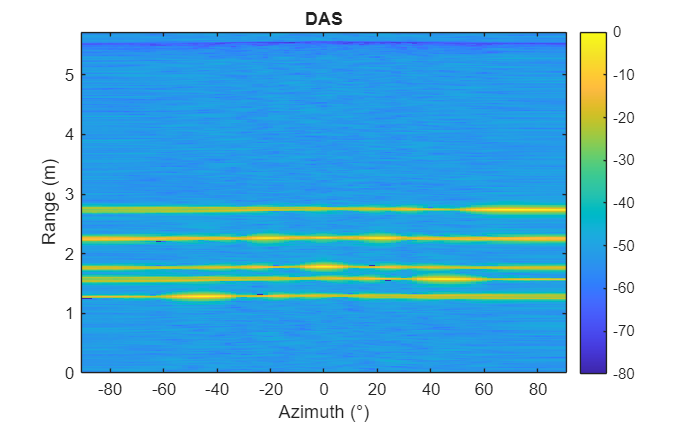

structImageDAS = structImage;
structImageDAS.methodImaging = 'DAS';
structImageDAS.coherenceType = 'none';
structImageDAS.methodProcessing = 'mexcuda'; 
imageDAS = clait.calculateAcousticImage(dataMicrophones, structSensor, structImageDAS);

maxRange = structSensor.numSamplesSensor / structSensor.sampleRate * 343 / 2;    
rangeVector = linspace( 0, maxRange, size( imageDAS, 1 ) );

dbCut = -80;
imageDASLog = normLog( imageDAS, dbCut );

figure(); 
imagesc( structImage.directionsAzimuth, rangeVector, imageDASLog )
xlabel( 'Azimuth (°)' )
ylabel( 'Range (m)')
set( gca, 'ydir', 'normal' )
title( 'DAS' )
colorbar
caxis( [ dbCut 0 ] )  

## Run full image calculation

processingMethod = 'mexcuda'; 

tic
% --- DAS ---
structImageDAS = structImage;
structImageDAS.methodImaging = 'DAS';
structImageDAS.coherenceType = 'none';
structImageDAS.methodProcessing = processingMethod; 
imageDAS = clait.calculateAcousticImage(dataMicrophones, structSensor, structImageDAS);

% --- DAS-CF ---
structImageDASCF = structImage;
structImageDASCF.methodImaging = 'DAS';
structImageDASCF.coherenceType = 'CF';
structImageDASCF.methodProcessing = processingMethod; 
imageDASCF = clait.calculateAcousticImage(dataMicrophones, structSensor, structImageDASCF);

% --- DMAS ---
structImageDMAS = structImage;
structImageDMAS.methodImaging = 'DMAS';
structImageDMAS.coherenceType = 'none';
structImageDMAS.methodProcessing = processingMethod; 
imageDMAS = clait.calculateAcousticImage(dataMicrophones, structSensor, structImageDMAS);

% --- DMAS-CF ---
structImageDMASCF = structImage;
structImageDMASCF.methodImaging = 'DMAS';
structImageDMASCF.coherenceType = 'CF';
structImageDMASCF.methodProcessing = processingMethod;
imageDMASCF = clait.calculateAcousticImage(dataMicrophones, structSensor, structImageDMASCF);

% --- DMAS3 ---
structImageDMAS3 = structImage;
structImageDMAS3.methodImaging = 'DMAS3';
structImageDMAS3.coherenceType = 'none';
structImageDMAS3.methodProcessing = processingMethod; 
imageDMAS3 = clait.calculateAcousticImage(dataMicrophones, structSensor, structImageDMAS3);

% --- DMAS3-CF  ---
structImageDMAS3CF = structImage;
structImageDMAS3CF.methodImaging = 'DMAS3';
structImageDMAS3CF.coherenceType = 'CF';
structImageDMAS3CF.methodProcessing = processingMethod; 
imageDMAS3CF = clait.calculateAcousticImage(dataMicrophones, structSensor, structImageDMAS3CF);

% --- DMAS4 ---
structImageDMAS4 = structImage;
structImageDMAS4.methodImaging = 'DMAS4';
structImageDMAS4.coherenceType = 'none';
structImageDMAS4.methodProcessing = processingMethod;
imageDMAS4 = clait.calculateAcousticImage(dataMicrophones, structSensor, structImageDMAS4);

% --- DMAS4-CF  ---
structImageDMAS4CF = structImage;
structImageDMAS4CF.methodImaging = 'DMAS4';
structImageDMAS4CF.coherenceType = 'CF';
structImageDMAS4CF.methodProcessing = processingMethod; 
imageDMAS4CF = clait.calculateAcousticImage(dataMicrophones, structSensor, structImageDMAS4CF);

% --- DMAS5 ---
structImageDMAS5 = structImage;
structImageDMAS5.methodImaging = 'DMAS5';
structImageDMAS5.coherenceType = 'none';
structImageDMAS5.methodProcessing = processingMethod; 
imageDMAS5 = clait.calculateAcousticImage(dataMicrophones, structSensor, structImageDMAS5);

% --- DMAS5-CF ---
structImageDMAS5CF = structImage;
structImageDMAS5CF.methodImaging = 'DMAS5';
structImageDMAS5CF.coherenceType = 'CF';
structImageDMAS5CF.methodProcessing = processingMethod;
imageDMAS5CF = clait.calculateAcousticImage(dataMicrophones, structSensor, structImageDMAS5CF);
toc

Elapsed time is 0.263269 seconds.


## Plot results

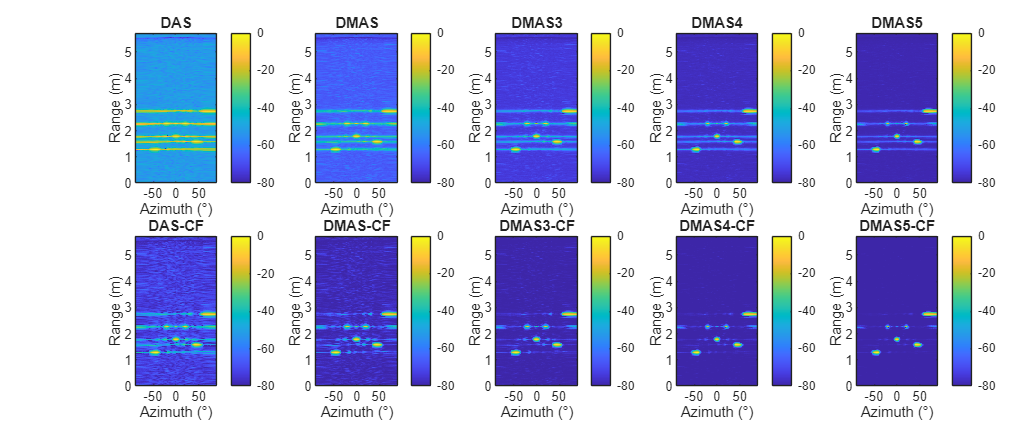

maxRange = structSensor.numSamplesSensor / structSensor.sampleRate * 343 / 2;    
rangeVector = linspace( 0, maxRange, size( imageDAS, 1 ) );    

dbCut = -80;
imageDASLog = normLog( imageDAS, dbCut );
imageDASCFLog = normLog( imageDASCF, dbCut );
imageDMASLog = normLog( imageDMAS, dbCut );
imageDMASCFLog = normLog( imageDMASCF, dbCut );
imageDMAS3Log = normLog( imageDMAS3, dbCut );
imageDMAS3CFLog = normLog( imageDMAS3CF, dbCut );
imageDMAS4Log = normLog( imageDMAS4, dbCut );
imageDMAS4CFLog = normLog( imageDMAS4CF, dbCut );
imageDMAS5Log = normLog( imageDMAS5, dbCut );
imageDMAS5CFLog = normLog( imageDMAS5CF, dbCut );

figure(); 
set(gcf, 'units','normalized','outerposition',[0 0 0.75 0.75]);
    tiledlayout( 2,5,'TileSpacing','tight','TileIndexing','columnmajor' )
    nexttile()
        imagesc( structImage.directionsAzimuth, rangeVector, imageDASLog )
        xlabel( 'Azimuth (°)' )
        ylabel( 'Range (m)')
        set( gca, 'ydir', 'normal' )
        title( 'DAS' )
        colorbar
       caxis( [ dbCut 0 ] )            
    nexttile()
        imagesc( structImage.directionsAzimuth, rangeVector, imageDASCFLog )
        xlabel( 'Azimuth (°)' )
        ylabel( 'Range (m)')
        set( gca, 'ydir', 'normal' )
        title( 'DAS-CF' )   
        colorbar
    nexttile()
        imagesc( structImage.directionsAzimuth, rangeVector, imageDMASLog )
        xlabel( 'Azimuth (°)' )
        ylabel( 'Range (m)')
        set( gca, 'ydir', 'normal' )
        title( 'DMAS' )    
        colorbar
       caxis( [ dbCut 0 ] )            
    nexttile()
        imagesc( structImage.directionsAzimuth, rangeVector, imageDMASCFLog )
        xlabel( 'Azimuth (°)' )
        ylabel( 'Range (m)')
        set( gca, 'ydir', 'normal' )
        title( 'DMAS-CF' ) 
        colorbar
       caxis( [ dbCut 0 ] )            
    nexttile()
        imagesc( structImage.directionsAzimuth, rangeVector, imageDMAS3Log )
        xlabel( 'Azimuth (°)' )
        ylabel( 'Range (m)')
        set( gca, 'ydir', 'normal' )
        title( 'DMAS3' )  
        colorbar
       caxis( [ dbCut 0 ] )            
    nexttile()
        imagesc( structImage.directionsAzimuth, rangeVector, imageDMAS3CFLog )
        xlabel( 'Azimuth (°)' )
        ylabel( 'Range (m)')
        set( gca, 'ydir', 'normal' )
        title( 'DMAS3-CF' )  
        colorbar
       caxis( [ dbCut 0 ] )            
    nexttile()
        imagesc( structImage.directionsAzimuth, rangeVector, imageDMAS4Log )
        xlabel( 'Azimuth (°)' )
        ylabel( 'Range (m)')
        set( gca, 'ydir', 'normal' )
        title( 'DMAS4' )   
        colorbar
        caxis( [ dbCut 0 ] )
    nexttile()
        imagesc( structImage.directionsAzimuth, rangeVector, imageDMAS4CFLog )
        xlabel( 'Azimuth (°)' )
        ylabel( 'Range (m)')
        set( gca, 'ydir', 'normal' )
        title( 'DMAS4-CF' )  
        colorbar
        caxis( [ dbCut 0 ] )
    nexttile()
        imagesc( structImage.directionsAzimuth, rangeVector, imageDMAS5Log )
        xlabel( 'Azimuth (°)' )
        ylabel( 'Range (m)')
        set( gca, 'ydir', 'normal' )
        title( 'DMAS5' )   
        colorbar
        caxis( [ dbCut 0 ] )
    nexttile()
        imagesc( structImage.directionsAzimuth, rangeVector, imageDMAS5CFLog )
        xlabel( 'Azimuth (°)' )
        ylabel( 'Range (m)')
        set( gca, 'ydir', 'normal' )
        title( 'DMAS5-CF' )  
        colorbar
        caxis( [ dbCut 0 ] )

## Helper functions

function dataMicrophonesOut = simulateMicrophoneData( structScene, structSensor )
%SIMULATEMICROPHONEDATA Simulates microphone data from point targets in a scene.
%
%   dataMicrophonesOut = SIMULATEMICROPHONEDATA(structScene, structSensor) 
%   generates a time-domain signal for each microphone by simulating the 
%   reflection of an emitted signal from a set of point targets. The simulation 
%   accounts for the time-of-flight from the emitter to each target and then 
%   to each microphone.
%
%   By Cosys-Lab, University of Antwerp
%   Contributors: Jan Steckel
%
%   INPUTS:
%   -----------------------------------------------------------------------
%   structScene      : Structure containing scene and target properties. (Mandatory)
%       .targetAzimuth      : Azimuth angles of point targets. [numTargets x 1] (deg)
%       .targetElevation    : Elevation angles of point targets. [numTargets x 1] (deg)
%       .targetRange        : Range (distance) to each point target. [numTargets x 1] (m)
%       .speedOfSound       : Speed of sound in the medium. [1 x 1] (m/s)
%       .targetStrength     : Amplitude of the reflection from each target. [numTargets x 1]
%
%   structSensor     : Structure containing sensor array setup and signal characteristics. (Mandatory)
%       .coordinatesEmitter     : Position of the sound source. [1 x 3] (m)
%       .coordinatesMicrophones : Positions of the microphone array elements. [numMics x 3] (m)
%       .numSamplesSensor       : Total number of samples to simulate. [1 x 1]
%       .sampleRate             : ADC sampling frequency. [1 x 1] (Hz)
%       .emissionSignal         : The transmitted signal. [numSamplesBase x 1]
%
%   OUTPUTS:
%   -----------------------------------------------------------------------
%   dataMicrophonesOut : The simulated microphone data.
%                        Dimensions: [numSamplesSensor x numMics].
%
%   NOTES:
%   - The function models reflections as simple time-of-flight delays and amplitude scaling.
%   - The final output is the convolution of the time-of-flight impulse response with the emission signal.
  
    [ pointsX, pointsY, pointsZ ] = sph2cart( deg2rad( structScene.targetAzimuth ), deg2rad( structScene.targetElevation ), structScene.targetRange  );
    targetsCartesian = [ pointsX ;pointsY ;pointsZ ]';
    
    numTargets = length( structScene.targetAzimuth );
    numChannels = size( structSensor.coordinatesMicrophones, 1 );
    
    dataMicrophones = zeros( structSensor.numSamplesSensor, numChannels );  
    for cntTarget = 1 : numTargets
        rangesToTarget = sqrt( sum(( structSensor.coordinatesEmitter - targetsCartesian( cntTarget, : ) ).^2, 2 ) );
        rangesFromTarget = sqrt( sum(( structSensor.coordinatesMicrophones - targetsCartesian( cntTarget, : ) ).^2, 2 ) );
        totalRanges = rangesToTarget + rangesFromTarget;
        totalTimeInSamples = round( totalRanges / structScene.speedOfSound *  structSensor.sampleRate );
    
        % rows = totalTimeInSamples(:);        % arrival times
        % cols = (1:numChannels)';             % channel indices
        % idx  = sub2ind(size(dataMicrophones), rows, cols);
    
        for cntChannel = 1 : numChannels
            curSample = totalTimeInSamples( cntChannel );
            dataMicrophones( curSample, cntChannel ) = dataMicrophones( curSample, cntChannel ) + structScene.targetStrength( cntTarget );
        end
    end
    dataMicrophonesOut = zeros( size( dataMicrophones ) );
    for cntChannel = 1 : numChannels
        dataMicrophonesOut( :, cntChannel ) = dataMicrophones( :, cntChannel ) + conv( dataMicrophones( :, cntChannel ), structSensor.emissionSignal, 'same' );
    end

end

function sig=fm_sweep(f_start,f_end,fs,duration, amplitude, winprct)
%FM_SWEEP Generates a hyperbolic FM sweep signal with Hanning windowing.
%
%   sig = FM_SWEEP(f_start, f_end, fs, duration, amplitude, winprct) generates 
%   a frequency-modulated (FM) sweep signal, often used as a bat-like call. 
%   The frequency changes hyperbolically from a start frequency to an end 
%   frequency over a specified duration. The signal is then windowed with a 
%   Hanning window at its start and end to prevent spectral leakage.
%
%   INPUTS:
%   -----------------------------------------------------------------------
%   f_start     : Start frequency of the sweep. [1 x 1] (Hz)
%
%   f_end       : End frequency of the sweep. [1 x 1] (Hz)
%
%   fs          : Sampling frequency. [1 x 1] (Hz)
%
%   duration    : Duration of the sweep. [1 x 1] (ms)
%
%   amplitude   : Amplitude of the generated signal. [1 x 1]
%
%   winprct     : Percentage of the signal duration to be covered by the 
%                 Hanning window at the start and end of the signal. [1 x 1] (%)
%
%   OUTPUTS:
%   -----------------------------------------------------------------------
%   sig         : The generated FM sweep signal vector. [nSamples x 1]
%
%   NOTES:
%   - The frequency modulation is linear with respect to the period (1/f).
%   - The `duration` input is in milliseconds and is converted to seconds internally.
%   - The total length of the Hanning window is `2*winprct/100` of the signal length.

    % The time scale is in milliseconds, convert to seconds
    ms = 10^-3; 
    duration = duration * ms; 
    
    % Generate time vector
    t = 0:1/fs:duration; 
    
    % Generate the frequency modulation vector (linear with the period)
    ft = 1./(1/f_start + t * (1/f_end - 1/f_start) / duration); 
    
    % Generate the FM sweep signal
    sig = amplitude * (sin(2*pi*(duration/(1/f_end-1/f_start)) * (log(1/f_start+t*(1/f_end-1/f_start)/duration) - log(1/f_start))));
    
    % Apply Hanning window to the start and end of the signal
    length_win = round(length(sig)*2*winprct/100);
    window_short = hanning(length_win);
    window_on = window_short(1:ceil(length_win/2));
    window_off = window_short(ceil(length_win/2) + 1 : end);
    window = ones(1,length(sig));
    window(1:length(window_on)) = window_on;
    window(end-length(window_off) + 1 : end) = window_off;
    
    sig = sig .* window; 
end

function [mat_out] = normLog(mat_in,threshDB)
%NORMLOG Normalizes a matrix and converts it to a logarithmic (dB) scale.
%
%   [mat_out] = NORMLOG(mat_in, threshDB) normalizes the input matrix `mat_in` 
%   to its global maximum, clips negative values to zero, and then converts 
%   the result to a logarithmic scale in decibels (dB), applying a threshold 
%   to prevent log(0) errors.
%
%   By Cosys-Lab, University of Antwerp
%   Contributors: Jan Steckel
%
%   INPUTS:
%   -----------------------------------------------------------------------
%   mat_in      : The input matrix or array of any dimension.
%
%   threshDB    : A threshold value in decibels (dB). Values below this 
%                 threshold (relative to the maximum) will be clamped to 
%                 this value in the output. [1 x 1] (dB)
%
%   OUTPUTS:
%   -----------------------------------------------------------------------
%   mat_out     : The normalized, thresholded, and log-scaled output matrix.
%                 Dimensions are the same as `mat_in`.
%
%   NOTES:
%   - The function normalizes the input matrix by dividing by its global maximum value.
%   - The `threshDB` value is converted to a linear scale and added to the 
%     matrix before the `log10` operation to handle values close to zero.
%   - Negative values in the input matrix are clipped to zero before log-scaling.
%
    
    thresh = 10^(threshDB/20);
    mat_out = mat_in / max(max(max(max(mat_in))));
    mat_out( mat_out < 0 ) = 0;
    mat_out = 20*log10( mat_out + thresh);
end